% DD_FORWARD_KINEMATICS_DEMO
% Simple simulation of differential-drive forward kinematics using R_dd.

clc; clear; close all;

% Load physical parameters (expects phys.r and phys.L)
[phys, ~] = mm_params_build_save_load('load', 'mm_params');

Loaded: mm_params.mat


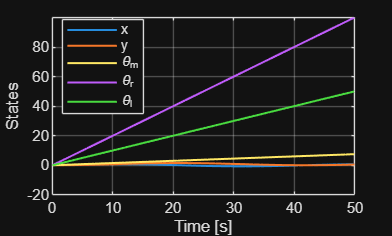


% Time span and initial state
tspan = [0 50];
X0    = [0; 0; 0; 0; 0];   % [x; y; theta_m; theta_r; theta_l]

% Wheel angular velocity inputs (rad/s)
theta_r_dot_fun = @(t) 2.0 .* (t >= 0);
theta_l_dot_fun = @(t) 1.0 .* (t >= 0);

% Integrate kinematics
odefun = @(t,X) mobile_kinematics_dd(t, X, theta_r_dot_fun, theta_l_dot_fun, phys);
[t, X] = ode45(odefun, tspan, X0);

% Plot states
figure;
plot(t, X, 'LineWidth', 1.2);
xlabel('Time [s]');
ylabel('States');
legend('x','y','\theta_m','\theta_r','\theta_l', 'Location', 'best');
grid on;

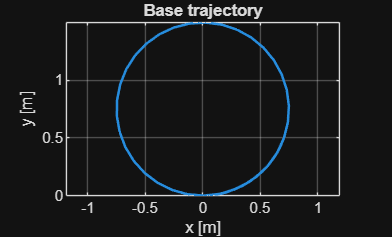


% Plot trajectory in XY plane
figure;
plot(X(:,1), X(:,2), 'LineWidth', 1.5);
xlabel('x [m]');
ylabel('y [m]');
axis equal; grid on;
title('Base trajectory');


% ===== Local function =====
function dX = mobile_kinematics_dd(t, X, theta_r_dot_fun, theta_l_dot_fun, phys)
    r = phys.r;
    L = phys.L;

    theta_m = X(3);

    u = [theta_r_dot_fun(t); theta_l_dot_fun(t)];
    R = R_dd(theta_m, r, L);

    dX = R * u;
end
function R = R_dd(theta_m, r, L)
% R_DD  Kinematic mapping for a differential-drive base.
%
%   q = [x; y; theta_m; theta_r; theta_l]   (5x1)
%   u = [theta_r_dot; theta_l_dot]         (2x1)
%
%   qdot = R_dd(theta_m, r, L) * u
%
% Columns of R span the nullspace of the nonholonomic constraints A(q) qdot = 0.

R = [ ...
    (r/2)*cos(theta_m),  (r/2)*cos(theta_m);  % x_dot
    (r/2)*sin(theta_m),  (r/2)*sin(theta_m);  % y_dot
     r/(2*L),           -r/(2*L);             % theta_m_dot
     1,                  0;                   % theta_r_dot
     0,                  1];                  % theta_l_dot
end
